clear; close; clc
minPrinces = [-2.973322E+05,-3.192327E+05,-3.322485E5]

minPrinces = 1.0e+05 *

   -2.9733   -3.1923   -3.3225


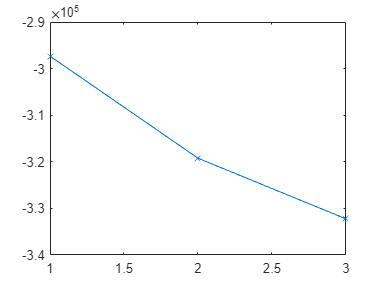

plot(minPrinces,"-x")

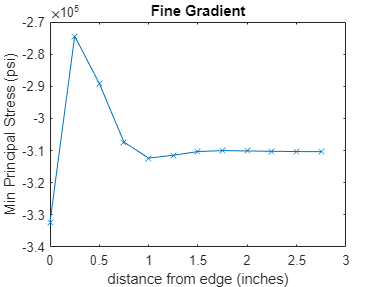



maxp = [
    3.038211E+05;
    3.273242E+05;
    3.245280E+05;
    ];


displacements = [
    1.236948E-03, 6.831180E+00, 8.887047E+00;
    4.979953E-09, 7.119062E+00, 9.116643E+00;
    2.506017E-09, 7.197069E+00, 9.176082E+00;
    ];


fineGradient = [
    -3.103425E+05,
    -3.103011E+05,
    -3.102348E+05,
    -3.101149E+05,
    -3.100142E+05,
    -3.102999E+05,
    -3.114438E+05,
    -3.123515E+05,
    -3.073643E+05,
    -2.891331E+05,
    -2.744139E+05,
    -3.322485E+05
    ];


mediumGradient = [
    -3.063436E+05,
    -3.058102E+05,
    -3.064954E+05,
    -3.093698E+05,
    -2.897105E+05,
    -3.191785E+05,
    ];

coarseGradient = [
    -2.900051E+05,
    -2.861737E+05,
    -2.928853E+05,
    -2.900515E+05
    ];


distFine = [11:-1:0]*1/4;
plot(distFine,fineGradient,"-x"); title("Fine Gradient"); ylabel("Min Principal Stress (psi)"); xlabel("distance from edge (inches)")

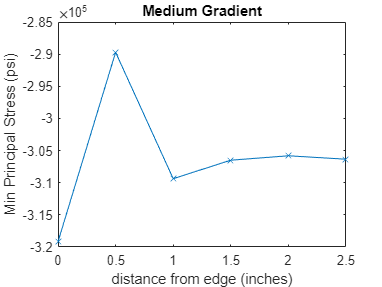


distMedium = distFine(2:2:end);
plot(distMedium,mediumGradient,"-x"); title("Medium Gradient"); ylabel("Min Principal Stress (psi)"); xlabel("distance from edge (inches)")

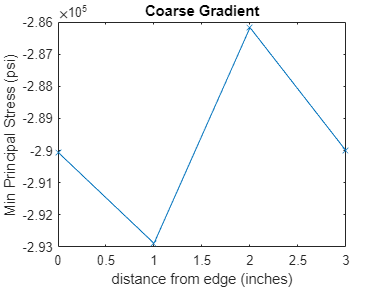


distCoarse = [3,distMedium(2:2:end)];
plot(distCoarse,coarseGradient,"-x"); title("Coarse Gradient"); ylabel("Min Principal Stress (psi)"); xlabel("distance from edge (inches)")

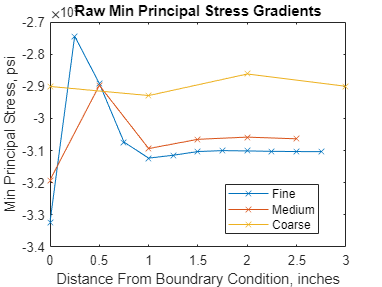


plot(distFine,fineGradient,"-x"); hold on;
plot(distMedium,mediumGradient,"-x");
plot(distCoarse,coarseGradient,"-x");
title("Raw Min Principal Stress Gradients"); ylabel("Min Principal Stress, psi"); xlabel('Distance From Boundrary Condition, inches'); legend("Fine","Medium","Coarse");
set(legend,'Location','best');

figure

fineFit = fit(distFine(4:8)',fineGradient(4:8),"poly1")

fineFit =      Linear model Poly1:
     fineFit(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =        2361  (467, 4255)
       p2 =  -3.144e+05  (-3.173e+05, -3.115e+05)

mediumFit = fit(distMedium(1:4)',mediumGradient(1:4),"poly1")

mediumFit =      Linear model Poly1:
     mediumFit(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =        1953  (-2721, 6627)
       p2 =  -3.104e+05  (-3.19e+05, -3.018e+05)

coarseFit = fit(distMedium(1:3)',coarseGradient(1:3),"poly1")

coarseFit =      Linear model Poly1:
     coarseFit(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =        2880  (-7.446e+04, 8.022e+04)
       p2 =  -2.954e+05  (-4.533e+05, -1.376e+05)


stresses = [fineGradient(1),mediumGradient(1),coarseGradient(1); fineGradient(4),mediumGradient(2),coarseGradient(1); fineGradient(8),mediumGradient(4),coarseGradient(2); fineGradient(12),mediumGradient(6),coarseGradient(3);]

stresses = 1.0e+05 *

   -3.1034   -3.0634   -2.9001
   -3.1011   -3.0581   -2.9001
   -3.1235   -3.0937   -2.8617
   -3.3225   -3.1918   -2.9289



distShort = [distFine(1),distFine(4),distFine(8),distFine(12)]

distShort =     2.7500    2.0000    1.0000         0


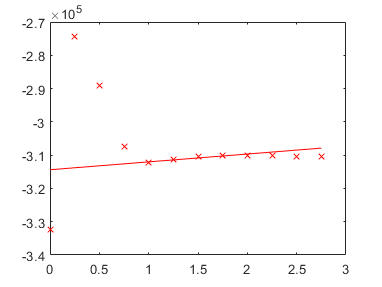


stressFitPoints = zeros(size(stresses));
for i = 1:size(stresses,1)
    stressFitPoints(i,1) = fineFit(distShort(i));
    stressFitPoints(i,2) = mediumFit(distShort(i));
    stressFitPoints(i,3) = coarseFit(distShort(i));
end



plot(distFine,fineGradient,"xr"); hold on;
plot(distShort,stressFitPoints(:,1),"-r");

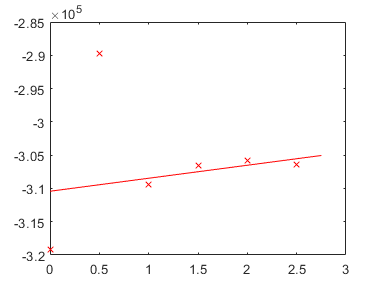

figure
plot(distMedium,mediumGradient,"xr"); hold on;
plot(distShort,stressFitPoints(:,2),"-r");

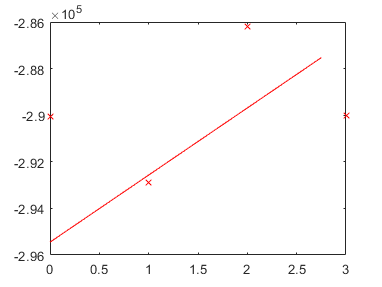

figure
plot(distCoarse,coarseGradient,"xr"); hold on;
plot(distShort,stressFitPoints(:,3),"-r");

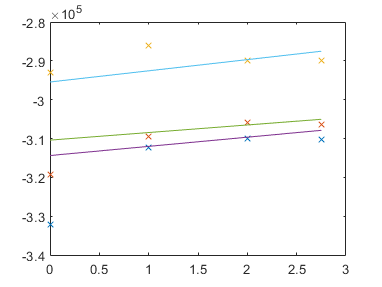


figure
plot(distShort,stresses(:,:),"x"); hold on;
plot(distShort,stressFitPoints(:,:),"-");

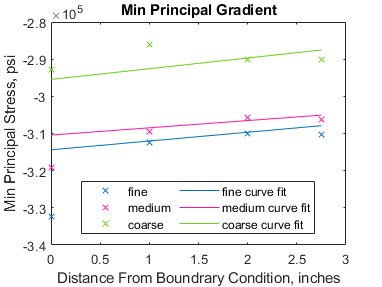


MinPrincipalGradient(distShort,[stresses,stressFitPoints])

## convergance

degFree = [9616,2504,676]

degFree =         9616        2504         676


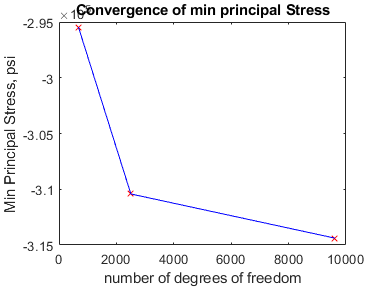


% min principal stress
figure;
plot(degFree,stressFitPoints(4,:),'xr');hold on;
plot(degFree,stressFitPoints(4,:),'-b');
ylabel("Min Principal Stress, psi");
xlabel("number of degrees of freedom");
title("Convergence of min principal Stress")

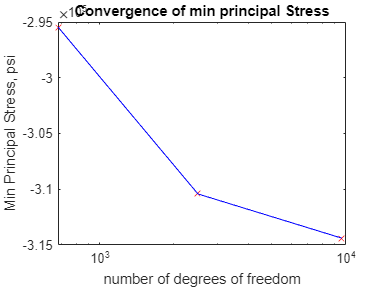


figure;
semilogx(degFree,stressFitPoints(4,:),'xr');hold on;
semilogx(degFree,stressFitPoints(4,:),'-b');
ylabel("Min Principal Stress, psi");
xlabel("number of degrees of freedom");
title("Convergence of min principal Stress")


% displacements
degfreeRev = fliplr(degFree)

degfreeRev =          676        2504        9616


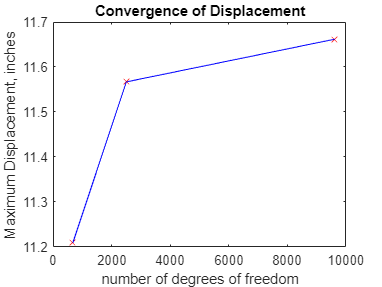

disps = (displacements(:,1).^2 + displacements(:,2).^2 + displacements(:,3).^2).^(1/2);

figure;
plot(degfreeRev,disps,'xr');hold on;
plot(degfreeRev,disps,'-b');
ylabel("Maximum Displacement, inches");
xlabel("number of degrees of freedom");
title("Convergence of Displacement")

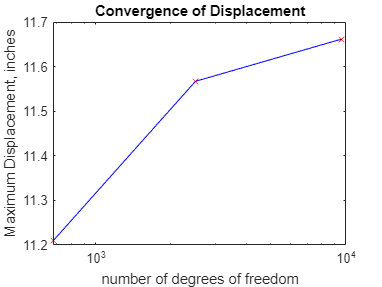


figure;
semilogx(degfreeRev,disps,'xr');hold on;
semilogx(degfreeRev,disps,'-b');
ylabel("Maximum Displacement, inches");
xlabel("number of degrees of freedom");
title("Convergence of Displacement")


% maximum principal stress
degfreeRev = fliplr(degFree)

degfreeRev =          676        2504        9616


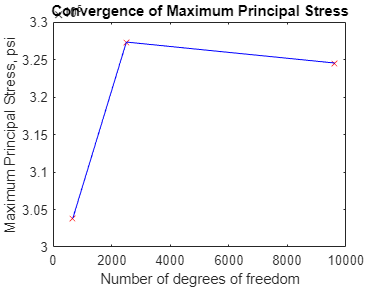


figure;
plot(degfreeRev,maxp,'xr');hold on;
plot(degfreeRev,maxp,'-b');
ylabel("Maximum Principal Stress, psi");
xlabel("Number of degrees of freedom");
title("Convergence of Maximum Principal Stress")

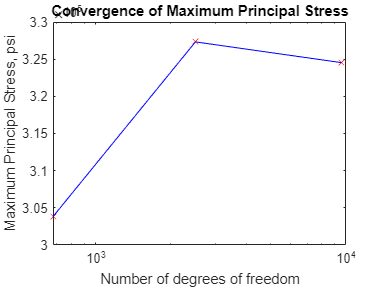


figure;
semilogx(degfreeRev,maxp,'xr');hold on;
semilogx(degfreeRev,maxp,'-b');
ylabel("Maximum Principal Stress, psi");
xlabel("Number of degrees of freedom");
title("Convergence of Maximum Principal Stress")